# **膜厚計測の自動データ処理**

#### **1.   コンセプト**

　現在**Sさん**から膜厚計測データをもらいました．**生データは直接使えないので，Excelに書き込む必要である．** 自動膜厚計は計測する時1列で順番通り記録しているため，自分のExcelファイルに正しい位置に入れ込むために，この一列を分けないといけない．

　計測は接合部孔回りの無機ジンクの膜厚，**不変な条件**としては：ボルト孔回り4箇所5回ずつ計測していな．回数=4x5x2x2x4=**320**

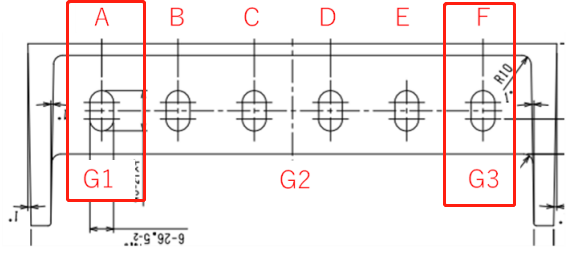     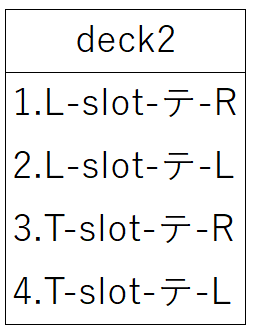

　　　　　　**Fig.１　Sさん実験膜厚計測箇所**　　　　　　　**Fig.2 計測順番**　

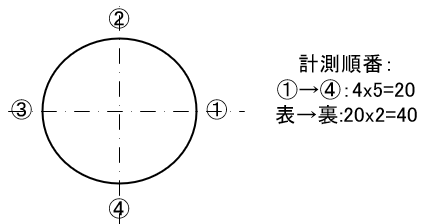

**Fig.3　ボルト孔回りの計測順番**

 **目標：**使えるデータになれるように，試験体ごと，ボルトごと，測る位置ごとに分けたい

#### **2．csvファイルの読み込む**

f = readmatrix('deck2.CSV')     %4列320行の行列を読み込まれた．

f =        NaN    1.0000  208.2000       NaN
       NaN    2.0000  177.7000       NaN
       NaN    3.0000  179.3000       NaN
       NaN    4.0000  161.1000       NaN
       NaN    5.0000  181.2000       NaN
       NaN    6.0000  183.4000       NaN
       NaN    7.0000  135.3000       NaN
       NaN    8.0000  162.9000       NaN
       NaN    9.0000  127.4000       NaN
       NaN   10.0000  135.1000       NaN


#### **3．行列変換**

f = f(:,3)                      %いらない列数を捨てる

f =   208.2000
  177.7000
  179.3000
  161.1000
  181.2000
  183.4000
  135.3000
  162.9000
  127.4000
  135.1000


f = reshape(f,5,[])             %行列の形変わる

f =   208.2000  183.4000  136.0000  192.7000  191.8000  173.8000  139.7000  182.0000  177.9000  169.7000  149.9000  135.5000  173.3000  178.3000  143.6000  169.5000  193.1000  164.5000  161.3000  157.2000  187.0000  146.9000  147.6000  150.7000  202.4000  124.7000  149.9000  154.1000  158.7000  159.7000  148.4000  159.5000  160.1000  153.7000  149.8000  161.9000  158.1000  161.8000  128.1000  130.5000  161.5000  151.8000  135.8000  159.1000  192.5000  151.7000  140.9000  165.0000  188.2000  185.2000
  177.7000  135.3000  152.5000  181.5000  182.1000  178.7000  126.9000  113.9000  193.1000  163.3000  153.9000  151.6000  155.0000  144.8000  176.2000  170.0000  155.2000  153.3000  189.7000  150.9000  171.3000  166.1000  158.6000  164.5000  155.3000  129.9000  138.7000  171.5000  181.1000  143.8000  132.8000  168.6000  158.2000  129.4000  165.8000  154.1000  139.9000  160.9000  123.1000  142.9000  179.1000  155.1000  146.9000  156.3000  174.4000  113.2000  128.2000  194.2000  199.5000  210

%[~,a] = size(data)             %行数を取得する

#### **4．Excelに書き込む**

　指定したExcelシートに書き込むことも当然可能だけど，コードを一回書き込むと，Sさんのシートに限定されたコードになるので，**直接コピペの方が早いと思います**．

#### **5.  フォルダ内のcsvファイルを全部読み取り**

clear
file = dir(fullfile('*.csv'))      %csvファイルの情報を全部取り

file = フィールドをもつ 6×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


filenames = {file.name}            %csvファイルの名前を取得

filenames = 1×6 の cell 配列
    {'L-menber.CSV'}    {'SlpicePlate.CSV'}    {'T1.CSV'}    {'deck2.CSV'}    {'deck3.CSV'}    {'床板１.CSV'}


[~,n] = size(filenames)            %csvファイルの個数を数える

n = 6

    data{i,2} = readmatrix(k{1,1})     %データを入れる

変数 k は未定義です。

    for i = 1 : n
    k = strcat(filenames(i))            %文字列に変換する
    data{i,1} = k{1,1}                 %名前を付けて
    end

#### **6.  読み込まれたcsvファイルを全部変換する**

　ループを回して全部のcsvファイルを変換する

for i = 1:n
    f = date{i,2}
    f = f(:,3)
    f = reshape(f,5,[])
    data{i,2} = f
end

#### **7.  最後にデータを保存する**

　保存するのは**Excelに書き込む**かそのまま**ワークスペース**として保存，どちらでも構いません．

便利上，ワークスペースとしてそのまま保存し，**Excelテンプレートがない時直接**コピペするのはおすすめする．

#### **8.  おまけ**

ヒストグラムの出力，平均値取るなどの機能も簡単に実現できる．

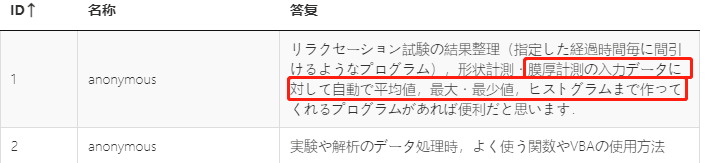

                                            Fig.４　Formsアンケートの抜粋

fig = readmatrix("deck2.CSV")
fig = fig(:,3)
%Normalization(fig)
histogram(fig)

#### 9.  自動変換スクリプト

clc
clear
file = dir(fullfile('*.csv'))      %csvファイルの情報を全部読み取り
filenames = {file.name}            %csvファイルの名前を取得
[~,n] = size(filenames)            %csvファイルの個数を数える
for i = 1 : n
    k = strcat(filenames(i))           %文字列に変換する
    data{i,1} = k{1,1}                 %名前を付けて
    data{i,2} = readmatrix(k{1,1})     %データを入れる
    f = data{i,2}
    f = f(:,3)
    f = reshape(f,5,[])
    data{i,2} = f
end
clearvars -except data